# Taller 2. Análisis Numérico y Computación Científica

Juan Manuel Ramirez

clear; clc;

- Métodos directos para resolver sistemas lineales: 

a. Resuelva los siguientes sistemas de ecuaciones empleando los métodos de eliminación gaussiana con sustitución hacia atrás, pivoteo parcial y pivoteo escalado. Concluya a partir de la comparación con la solución exacta y con el número de operaciones entre los tres métodos:

i. 


$$2x_1-6x_2-x_3=-38\\
-3x_1-x_2+7x_3=-34\\
-8x_1+x_2-2x_3=-20
$$


m1a1 = [2 -6 -1;
    -3 -1 7;
    -8 1 -2]

m1a1 =      2    -6    -1
    -3    -1     7
    -8     1    -2


b1a1 = [-38; -34; -20]

b1a1 =    -38
   -34
   -20



rea1al = m1a1\b1a1

rea1al =      4
     8
    -2



[x1a11, con1a11] = pivoteo(m1a1, b1a1, 'gaussiana', 0, 1)

x1a11 =     4.0000
    8.0000
   -2.0000


con1a11 = 15

[x1a12, con1a12] = pivoteo(m1a1, b1a1, 'parcial', 0, 1)

x1a12 =      4
     8
    -2


con1a12 = 21

[x1a13, con1a13] = pivoteo(m1a1, b1a1, 'escalado', 0, 1)

x1a13 =      4
     8
    -2


con1a13 = 27

En este caso los resultados dieron iguales al resultado real para los tres metodos. La diferencia se encuentra en la cantidad de operaciones realizadas. El metodo de eliminacion gaussiana al ser la base y no requerir pasos extra es el mas eficiente para resolver este problema.

ii. 


$$-3x_2-7x_3=2\\
x_1+2x_2-x_3=3\\
5x_1-2x_2=2
$$


m1a2 = [0 -3 7;
    1 2 -1;
    5 -2 0]

m1a2 =      0    -3     7
     1     2    -1
     5    -2     0


b1a2 = [2; 3; 2]

b1a2 =      2
     3
     2



real1a2 = m1a2\b1a2

real1a2 =     0.9855
    1.4638
    0.9130



[x1a21, con1a21] = pivoteo(m1a2, b1a2, 'gaussiana', 0, 1)

x1a21 =    NaN
   NaN
   NaN


con1a21 = 15

[x1a22, con1a22] = pivoteo(m1a2, b1a2, 'parcial', 0, 1)

x1a22 =     0.9855
    1.4638
    0.9130


con1a22 = 21

[x1a23, con1a23] = pivoteo(m1a2, b1a2, 'escalado', 0, 1)

x1a23 =     0.9855
    1.4638
    0.9130


con1a23 = 27

Para este caso se encuentra que el metodo gaussiano es el unico que no logra llegar a la solucion, esto se debe a que la primera fila de la primera columna tiene un 0 el cual se intenta convertir en un 1. Por parte de lacantidad de operaciones se encuentra que el metodo parcial otra vez requiere menos que el escalado y por tanto el mejor metodo para este caso es el parcial.

b. Utilice la factorización matricial para determinar la matriz inversa y la solución del sistema:


$$3x_1-0.1x_2-0.2x_3=7.85\\
0.1x_1+7x_2-0.3x_3=-19.3\\
0.3x_1-0.2x_2+10x_3=71.4
$$


Para ello tenga en cuenta que si la matriz inversa de la matriz 𝐴 se denota con 𝑀 = 𝐴 −1 , la columna 𝑛 − é𝑠𝑖𝑚𝑎 de 𝑀 se podrá encontrar mediante:


$$Ld = c \\ Ux = d$$


Donde el vector 𝑐 corresponde a un vector con un 1 en la 𝑛 −é𝑠𝑖𝑚𝑎 fila y ceros en las demás. Así:


$$M(:,n)=x$$


m1b = [3 -0.1 -0.2;
    0.1 7 -0.3;
    0.3 -0.2 10]

m1b =     3.0000   -0.1000   -0.2000
    0.1000    7.0000   -0.3000
    0.3000   -0.2000   10.0000


b1b = [7.85; -19.3; 71.4]

b1b =     7.8500
  -19.3000
   71.4000



real1bx = m1b\b1b

real1bx =     3.0000
   -2.5000
    7.0000


real1bM = inv(m1b)

real1bM =     0.3325    0.0049    0.0068
   -0.0052    0.1429    0.0042
   -0.0101    0.0027    0.0999



[M,x] = factorizacion(m1b,b1b)

M =     0.3325    0.0049    0.0068
   -0.0052    0.1429    0.0042
   -0.0101    0.0027    0.0999


x =     3.0000
   -2.5000
    7.0000


2. Métodos iterativos para resolver sistemas lineales

a. Utilice el método de Jacobi y de Gauss – Siedel para resolver los siguientes sistemas de ecuaciones con un error estimado menor del 0.1%: 

i. 


$$15c_1-3c_2-1c_3=3800\\
-3c_1+18c_2-6c_3=1200\\
-4c_1-c_2+12c_3=2350
$$
    

a2a = [15 -3 -1;
    -3 18 -6;
    -4 -1 12]

a2a =     15    -3    -1
    -3    18    -6
    -4    -1    12


b2a = [3800; 1200; 2350]

b2a =         3800
        1200
        2350



x12a = [3800/15; 1200/18; 2350/12]

x12a =   253.3333
   66.6667
  195.8333



iterativos(a2a, b2a, x12a, 10^(-3), 'jacobi') 

ans =   320.1013
  227.0453
  321.3735


iterativos(a2a, b2a, x12a, 10^(-3), 'gauss-siedel')

ans =   320.1923
  227.1896
  321.4966


a2a\b2a

ans =   320.2073
  227.2021
  321.5026


b. Utilice el método de Jacobi y de Gauss – Siedel para resolver los tres ejercicios del numeral 1 de este taller con un error estimado menor del 0.1%

% Preguntar si cambiar inversa de la funcion por la factorizacion

[~,i1a1] = max(abs(m1a1),[], 2,"linear");
%b1a1./m1a1(i1a1)
iterativos(m1a1, b1a1, [0; 0; 0], 10^(-3), 'jacobi') 

ans = 1.0e+308 *

   -0.0397
      -Inf
   -1.1047


iterativos(m1a1, b1a1, b1a1./m1a1(i1a1), 10^(-3), 'gauss-siedel')

ans =    Inf
   NaN
  -Inf


m1a1\b1a1

ans =      4
     8
    -2



% m1a2 cambiar filas 1 y 3
m1a2b = m1a2;
m1a2b([1 3],:) = m1a2b([3 1],:);
iterativos(m1a2b, b1a2, b1a2./max(m1a2,[], 2), 10^(-3), 'jacobi') 

ans =     0.9860
    1.4638
    0.9136


iterativos(m1a2b, b1a2, b1a2./max(m1a2,[], 2), 10^(-3), 'gauss-siedel')

ans =     0.9855
    1.4638
    0.9130


m1a2\b1a2

ans =     0.9855
    1.4638
    0.9130



iterativos(m1b, b1b, b1b./max(m1b,[], 2), 10^(-3), 'jacobi') 

ans =     3.0000
   -2.5000
    7.0000


iterativos(m1b, b1b, b1b./max(m1b,[], 2), 10^(-3), 'gauss-siedel')

ans =     3.0002
   -2.5000
    7.0000


m1b\b1b

ans =     3.0000
   -2.5000
    7.0000


En el primer punto se encuentran problemas para hallar la solucion. Este resultado se da por falta de convergencia de la matriz. Al encontrar los valores propios se encuentran 8.506, -4.753+4.611i y -4.753-4.611i. De modo que el radio espectral de la matriz es mayor a 1. Por lo cual el resultado esperado por medio de estos metodos es no converger.

Notese que para el segundo caso se requirio cambiar las filas 1 y 3 para obtener una solucion. De lo contrario se llega a indeterminaciones al invertir D y D-L.

c. Utilice refinamiento iterativo para resolver los tres ejercicios del numeral 1 de este taller con una precisión de 5 dígitos.

refinamiento(m1a1, b1a1, pivoteo(m1a1, b1a1,'redondeo',1, 0), 10^(-1), 5)

ans =     3.9635
    7.9583
   -1.9750



refinamiento(m1a2, b1a2, pivoteo(m1a2, b1a2,'redondeo',1, 0), 10^(-1), 5)

ans =     0.9333
    1.4333
    0.8667



refinamiento(m1b,b1b, pivoteo(m1b,b1b,'redondeo',1, 0), 10^(-1), 5)

ans =     3.0333
   -2.5571
    7.0000


3. Regresión por mínimos cuadrados:

a. Para la siguiente tabla de datos:

x3a = [5 10 15 20 25 30 35 40 45 50]

x3a =      5    10    15    20    25    30    35    40    45    50


y3a = [17 24 31 33 37 37 40 40 42 41]

y3a =     17    24    31    33    37    37    40    40    42    41


i. Ajuste los datos a una línea recta

as3a1 = regresion(x3a, y3a)

as3a1 =    20.6000
    0.4945


ii. Ajuste los datos a un modelo de tasa de crecimiento de saturación 

as3a2 = regresion(1./x3a,1./y3a)

as3a2 =     0.0200
    0.1975


as3a2(1) = 1/as3a2(1)

as3a2 =    50.0921
    0.1975


as3a2(2) = as3a2(2)*as3a2(1)

as3a2 =    50.0921
    9.8914


iii. Ajuste los datos a una ecuación de potencias

as3a3 = regresion(log(x3a),log(y3a))

as3a3 =     2.2979
    0.3851


as3a3(1) = exp(as3a3(1))

as3a3 =     9.9529
    0.3851


iv. Ajuste los datos a una parábola

as3a4 = regresion([x3a;x3a.^2], y3a)

as3a4 =    11.7667
    1.3779
   -0.0161


v. Grafique la tabla de datos y los ajustes encontrados en el intervalo en que están contenidos los datos.

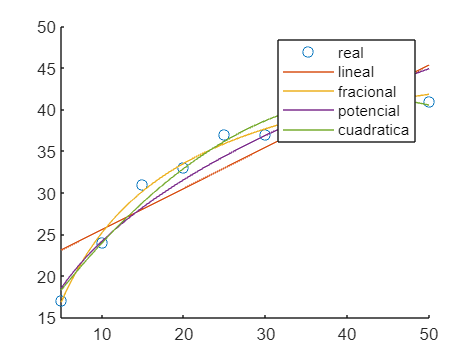

syms t
scatter(x3a,y3a)
hold on
xl3a = 5:0.1:50;
plot(xl3a,polyval([as3a1(2) as3a1(1)],xl3a))

fplot(as3a2(1)*t/(as3a2(2)+t))


fplot(as3a3(1)*t^as3a3(2))

plot(xl3a,polyval(flip(as3a4),xl3a))
hold off
xlim([5,50])
legend('real', 'lineal', 'fracional', 'potencial', 'cuadratica')

vi. ¿Existe algún ajuste superior a los demás? Justifique. 

sum((y3a-(x3a.*as3a1(2)+as3a1(1))).^2)

ans = 97.1636

sum((y3a-(x3a.*as3a2(1)./(as3a2(2)+x3a))).^2)

ans = 6.5031

sum((y3a-(as3a3(1)*x3a.^as3a3(2))).^2)

ans = 37.4796

sum((y3a-polyval(flip(as3a4),x3a)).^2)

ans = 12.0424

Visualmente se puede considerar que la fraccional es la que mejor se ajusta a los valores, sin embargo la distancia con los puntos deja en duda esta afirmacion. Calculando la suma de errores cuadrados se puede confirmar que la fraccional si es la mejor al tener un menor error.

b. Para la siguiente tabla de datos:

x3b = [3 4 5 7 8 9 11 12]

x3b =      3     4     5     7     8     9    11    12


y3b = [1.6 3.6 4.4 3.4 2.2 2.8 3.8 4.6]

y3b =     1.6000    3.6000    4.4000    3.4000    2.2000    2.8000    3.8000    4.6000


i. Aproxime los datos mediante un polinomio genérico de grado 3, grado 4 y grado 5

% preguntar por aproximacion o regresion

as3b13 = aproximacion([x3b;y3b], 1, length(x3b), 'polinomio_discreto', 3, 4)

as3b13 =    -8.5860
    5.7574
   -0.8492
    0.0389


as3b14 = aproximacion([x3b;y3b], 1, length(x3b), 'polinomio_discreto', 4, 4)

as3b14 =   -36.0075
   23.0803
   -4.6817
    0.3939
   -0.0117


as3b15 = aproximacion([x3b;y3b], 1, length(x3b), 'polinomio_discreto', 5, 4)

as3b15 =    -9.1393
    1.7739
    1.7512
   -0.5341
    0.0525
   -0.0017


ii. Aproxime los datos mediante funciones ortogonales (Polinomios de Legendre)

%t = (2*x-(b+a))/(b-a)  -->  (2*x-15)/9  12 3
%x = (t*(b-a)+(b+a))/2  -->  (9x+15)/2
as3b23 = aproximacion([(2*x3b-15)/9;y3b], 1, length(x3b), 'legendre_discreto', 3, 4)

as3b23 = 4x1
    3.3889
    0.1259
    0.0093
    1.1319


as3b24 = aproximacion([(2*x3b-15)/9;y3b], 1, length(x3b), 'legendre_discreto', 4, 4)

as3b24 = 5x1
    3.3889
    0.1259
    0.0093
    1.1319
   -1.5010


as3b25 = aproximacion([(2*x3b-15)/9;y3b], 1, length(x3b), 'legendre_discreto', 5, 4)

as3b25 = 6x1
    3.3889
    0.1259
    0.0093
    1.1319
   -1.5010
   -1.2418


iii. Grafique la tabla de datos y los polinomios de aproximación obtenidos en el intervalo en que están contenidos los datos.

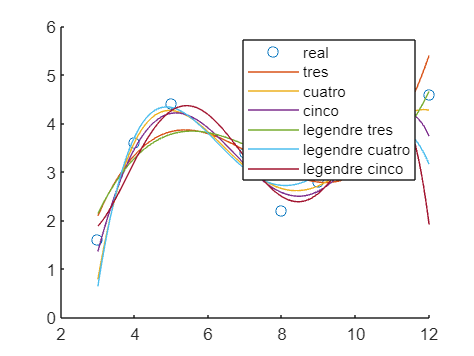

scatter(x3b, y3b)
hold on
xl3b = x3b(1):0.01:x3b(end);
plot(xl3b,polyval(flip(as3b13),xl3b))
plot(xl3b,polyval(flip(as3b14),xl3b))
plot(xl3b,polyval(flip(as3b15),xl3b))
p1 = 0;
%p0(x) = x.^0;
p0 = 1;
l3b3 = 0;
l3b4 = 0;
l3b5 = 0;
for i = 1:4
    l3b3 = l3b3 + p0*as3b23(i);
    l3b4 = l3b4 + p0*as3b24(i);
    l3b5 = l3b5 + p0*as3b25(i);
    p2 = p1;
    p1 = p0;
    p0 = ((2*(i-1)+1)*((2*xl3b-15)/9).*p1-(i-1)*p2)/i;
end
l3b4 = l3b4 + p0*as3b24(5);
l3b5 = l3b5 + p0*as3b25(5);
p2 = p1;
p1 = p0;
p0 = ((2*(4)+1)*((2*xl3b-15)/9).*p1-(4)*p2)/5;
l3b5 = l3b5 + p0*as3b25(6);
plot(xl3b,l3b3)
plot(xl3b,l3b4)
plot(xl3b,l3b5)
hold off
legend('real', 'tres', 'cuatro', 'cinco', 'legendre tres', 'legendre cuatro', 'legendre cinco')

iv. Encuentre el error estimado y el coeficiente de correlación

p1 = 0;
%p0(x) = x.^0;
p0 = 1;
l3b3 = 0;
l3b4 = 0;
l3b5 = 0;
for i = 1:4
    l3b3 = l3b3 + p0*as3b23(i);
    l3b4 = l3b4 + p0*as3b24(i);
    l3b5 = l3b5 + p0*as3b25(i);
    p2 = p1;
    p1 = p0;
    p0 = ((2*(i-1)+1)*((2*x3b-15)/9).*p1-(i-1)*p2)/i;
end
l3b4 = l3b4 + p0*as3b24(5);
l3b5 = l3b5 + p0*as3b25(5);
p2 = p1;
p1 = p0;
p0 = ((2*4+1)*((2*x3b-15)/9).*p1-4*p2)/5;
l3b5 = l3b5 + p0*as3b25(6);


S3b13 = sum((y3b - polyval(flip(as3b13),x3b)).^2)

S3b13 = 1.9619

S3b14 = sum((y3b - polyval(flip(as3b14),x3b)).^2)

S3b14 = 1.1240

S3b15 = sum((y3b - polyval(flip(as3b15),x3b)).^2)

S3b15 = 1.2021

S3b23 = sum((y3b - l3b3).^2)

S3b23 = 1.9521

S3b24 = sum((y3b - l3b4).^2)

S3b24 = 3.4580

S3b25 = sum((y3b - l3b5).^2)

S3b25 = 8.0594


y3bm = mean(y3b);
St3b = sum((y3b-y3bm).^2);
r3b13 = sqrt((St3b-S3b13)/St3b)

r3b13 = 0.8613

r3b14 = sqrt((St3b-S3b14)/St3b)

r3b14 = 0.9231

r3b15 = sqrt((St3b-S3b15)/St3b)

r3b15 = 0.9175

r3b23 = sqrt((St3b-S3b23)/St3b)

r3b23 = 0.8621

r3b24 = sqrt((St3b-S3b24)/St3b)

r3b24 = 0.7382

r3b25 = sqrt((St3b-S3b25)/St3b)

r3b25 = 0.0000 + 0.2459i

c. Utilizando polinomios de Legendre: 

i. Sea la función $f(x) = e^x$ en el intervalo [−1,1]. Aproxime la función mediante una recta y una parábola de mínimos cuadrados. Compare las dos gráficas. 

syms x
f3c1(x) = exp(x);
fplot(f3c1)
hold on
xl3c1 = -1:0.1:1;
as3c1l = aproximacion(f3c1, -1, 1, 'legendre', 1, 4)

as3c1l = 2x1
    1.1752
    1.1036


as3c1p = aproximacion(f3c1, -1, 1, 'legendre', 2, 4)

as3c1p = 3x1
    1.1752
    1.1036
    0.3578


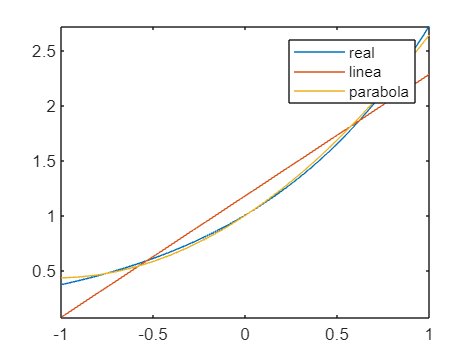


p1 = 0; p0 = 1; l3c1l = 0; l3c1p = 0;
for i = 1:2
    l3c1l = l3c1l + p0*as3c1l(i);
    l3c1p = l3c1p + p0*as3c1p(i);
    p2 = p1;
    p1 = p0;
    p0 = ((2*(i-1)+1)*xl3c1.*p1-(i-1)*p2)/i;
end
l3c1p = l3c1p + p0*as3c1p(3);
plot(xl3c1,l3c1l)
plot(xl3c1,l3c1p)
hold off
xlim([-1 1])
legend('real', 'linea', 'parabola')

ii, Aproxime la función $f(x) = \frac{1}{x}$ en el intervalo [1,2] por una recta, una parábola y una ecuación cúbica de mínimos cuadrados. Compare gráficamente.

syms x
%t = (2*x-(b+a))/(b-a)  -->  2*x-3
%x = (t*(b-a)+(b+a))/2  -->  (x+3)/2
f3c2(x) = 1/x;
fplot(f3c2)
f3c2(x) = 2/(x+3);
hold on
xl3c2 = 1:0.1:2;
as3c2l = aproximacion(f3c2, -1, 1, 'legendre', 1, 4)

as3c2l = 2x1
    0.6931
   -0.2383


as3c2p = aproximacion(f3c2, -1, 1, 'legendre', 2, 4)

as3c2p = 3x1
    0.6931
   -0.2383
    0.0546


as3c2c = aproximacion(f3c2, -1, 1, 'legendre', 3, 4)

as3c2c = 4x1
    0.6931
   -0.2383
    0.0546
   -0.0112


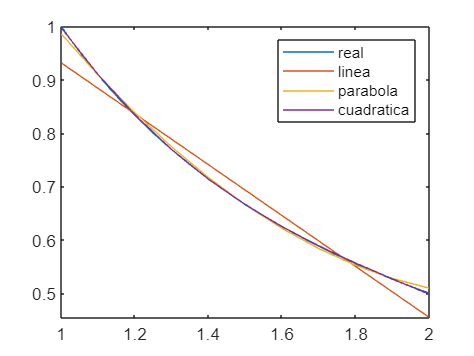


p1 = 0; p0 = 1; l3c2l = 0; l3c2p = 0; l3c2c = 0;
for i = 1:2
    l3c2l = l3c2l + p0*as3c2l(i);
    l3c2p = l3c2p + p0*as3c2p(i);
    l3c2c = l3c2c + p0*as3c2c(i);
    p2 = p1;
    p1 = p0;
    p0 = ((2*(i-1)+1)*(2*xl3c2-3).*p1-(i-1)*p2)/i;
end
l3c2p = l3c2p + p0*as3c2p(3);
l3c2c = l3c2c + p0*as3c2c(3);
p2 = p1;
p1 = p0;
p0 = ((2*2+1)*(2*xl3c2-3).*p1-2*p2)/3;
l3c2c = l3c2c + p0*as3c2c(4);
plot(xl3c2,l3c2l)
plot(xl3c2,l3c2p)
plot(xl3c2,l3c2c)

hold off
xlim([1 2])
legend('real', 'linea', 'parabola', 'cuadratica')

iii. Aproxime la función $f(x) = (2x)^3$ en el intervalo [0,1] mediante una recta y una parábola de mínimos cuadrados. Compare las dos gráficas

syms x
%t = (2*x-(b+a))/(b-a)  --> 2*x-1
%x = (t*(b-a)+(b+a))/2  --> (x+1)/2
f3c3(x) = (2*x)^3;
fplot(f3c3)
f3c3(x) = (x+1)^3;
hold on
xl3c3 = 0:0.1:1;
as3c3l = aproximacion(f3c3, -1, 1, 'legendre', 1, 4)

as3c3l = 2x1
    2.0000
    3.6000


as3c3p = aproximacion(f3c3, -1, 1, 'legendre', 2, 4)

as3c3p = 3x1
    2.0000
    3.6000
    2.0000


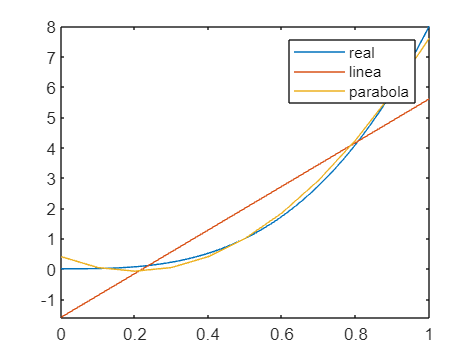


p1 = 0; p0 = 1; l3c3l = 0; l3c3p = 0;
for i = 1:2
    l3c3l = l3c3l + p0*as3c3l(i);
    l3c3p = l3c3p + p0*as3c3p(i);
    p2 = p1;
    p1 = p0;
    p0 = ((2*(i-1)+1)*(2*xl3c3-1).*p1-(i-1)*p2)/i;
end
l3c3p = l3c3p + p0*as3c3p(3);
plot(xl3c3,l3c3l)
plot(xl3c3,l3c3p)
hold off
xlim([0 1])
legend('real', 'linea', 'parabola')

d. Utilice las series de Fourier para encontrar la aproximación de: 

i. La siguiente función:

syms x
f3d(x) = abs(x);
fplot(f3d)
hold on
n3d1 = 10;
as3d1 = aproximacion(f3d, -1, 1, 'fourier continua', n3d1, 20)

as3d1 = 11x2
    1.0000         0
   -0.4053         0
         0         0
   -0.0450         0
         0         0
   -0.0162         0
         0         0
   -0.0083         0
         0         0
   -0.0050         0


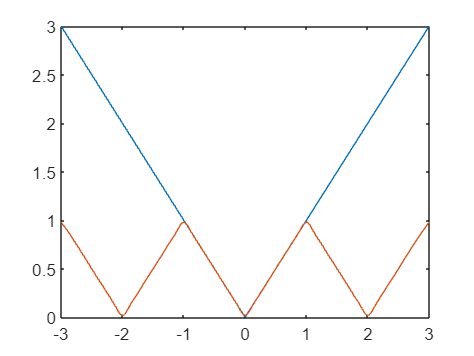

g3d1(x) = as3d1(1,1)*x^0/2;
w = pi;
for i = 1:n3d1
    g3d1 = g3d1 + as3d1(i+1,1)*cos(i*w*x) + as3d1(i+1,2)*sin(i*w*x);
end
fplot(g3d1)

hold off
xlim([-3,3])

ii. La siguiente tabla de datos:

x3d2 = 0:0.1:6.2;
y3d2 = [1.9990 0.5253 0.8726 0.8509 -0.1269 0.0000 0.1269 -0.8509 -0.8726 -0.5253 -1.9990 -0.5253 -0.8726 -0.8509 0.1269 0.0000 -0.1269 0.8509 0.8726 0.5253 1.9990 0.5253 0.8726 0.8509 -0.1269 0.0000 0.1269 -0.8509 -0.8726 -0.5253 -1.9990 -0.5253 -0.8726 -0.8509 0.1269 0.0000 -0.1269 0.8509 0.8726 0.5253 1.9990 0.5253 0.8725 0.8509 -0.1269 0.0000 0.1269 -0.8509 -0.8726 -0.5253 -1.9990 -0.5253 -0.8726 -0.8509 0.1269 0 -0.1269 0.8509 0.8726 0.5253 1.9990 0.5253 0.8726]

y3d2 = 1x63
    1.9990    0.5253    0.8726    0.8509   -0.1269         0    0.1269   -0.8509   -0.8726   -0.5253   -1.9990   -0.5253   -0.8726   -0.8509    0.1269         0   -0.1269    0.8509    0.8726    0.5253    1.9990    0.5253    0.8726    0.8509   -0.1269         0    0.1269   -0.8509   -0.8726   -0.5253


scatter(x3d2, y3d2)
hold on
n3d2 = 30;
as3d2 = aproximacion([x3d2;y3d2], 1, 62, 'fourier discreta', n3d2, 20)

as3d2 = 31x2
    0.0814         0
    0.0911   -0.0137
    0.1399   -0.0422
    0.9629   -0.4378
   -0.1386    0.0848
   -0.0560    0.0433
   -0.0310    0.0289
   -0.0180    0.0186
   -0.0079    0.0039
    0.0134   -0.0650


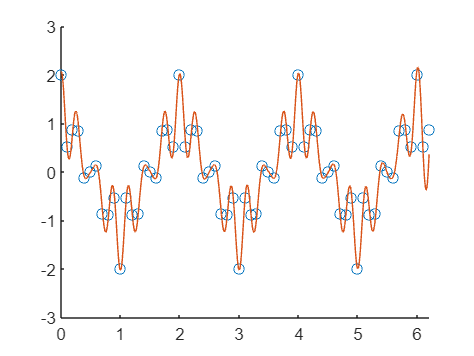

g3d2(x) = as3d2(1,1)*x^0/2;
for i = 1:n3d2
    g3d2 = g3d2 + as3d2(i+1,1)*cos(i*x) + as3d2(i+1,2)*sin(i*x);
end
fplot(g3d2)
hold off
xlim([0,6.2])